## **1. Code description & copyright notice**

%EXAMPLE_ADB
% Creates an example aerodynamic database (in AoA/AoS) using ADBSat
%
% Author: Nicholas Crisp
% The University of Manchester
% November 2022
%
%--- Copyright notice ---%
% Copyright (C) 2022 The University of Manchester
% Written by David Mostaza Prieto,  Nicholas H. Crisp, Luciana Sinpetru and Sabrina Livadiotti
%
% This file is part of the ADBSat toolkit.
%
% This program is free software: you can redistribute it and/or modify it
% under the terms of the GNU General Public License as published by
% the Free Software Foundation, either version 3 of the License, or (at
% your option) any later version.
%
% This program is distributed in the hope that it will be useful, but
% WITHOUT ANY WARRANTY; without even the implied warranty of
% MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE. See the GNU General
% Public License for more details.
%
% You should have received a copy of the GNU General Public License along
% with this program. If not, see <http://www.gnu.org/licenses/>.
%------------- BEGIN CODE --------------

## **2.Code **

### **2.1 Setting input and output file directories**

clear; close all; clc

modName = 'sphere'

modName = 'sphere'

% Path to model file
ADBSat_path = ADBSat_dynpath;
modIn = fullfile(ADBSat_path,'inou','obj_files',[modName,'.obj']);
modOut = fullfile(ADBSat_path,'inou','models');
resOut = fullfile(ADBSat_path,'inou','results');

### 2.2 Input conditions

%Input conditions
alt = 200; %km
inc = 51.6; %deg
%env = [alt*1e3, inc/2, 0, 106, 0, 65, 65, ones(1,7)*3, 0]; % Environment variables
inparam = struct;
inparam = environment (inparam, alt*1e3, inc/2, 0, 106, 0, 300, 300, ones(1,7)*3,0);
%Angle of attacck & Angle of sideslip ranges
aoa_min = -45;
aoa_max =  45;
aos_min = -45;
aos_max =  45;

aoa = aoa_min:1:aoa_max; % Angle of attack
aos = aoa_min:1:aoa_max; % Angle of sideslip

### 2.3 Model parameters

% Model parameters
shadow = 1;
inparam.gsi_model       = 'DRIA';
%inparam.alpha = 1; % Accommodation (altitude dependent)
accommodation_model     = "SESAM" % Choose the accommodation model

accommodation_model = "SESAM"

if accommodation_model == 'Goodman'
    inparam.alpha = accom_goodman(inparam);
end
if accommodation_model == 'SESAM'
    inparam.alpha = accom_SESAM(inparam);
end
if accommodation_model == 'Constant'
    prompt = 'Please enter accommodation coefficient value \n\n\n';
    inparam.alpha = input(prompt);
end

inparam.Tw = 300; % Wall Temperature [K]

solar = 1;
inparam.sol_cR = 0.15; % Specular Reflectivity
inparam.sol_cD = 0.25; % Diffuse Reflectivity
inparam.alphaN = 0.5;
inparam.sigmaT = 0.5;
inparam.sigmaN = 0.5;

verb = 0; % Verbose
del = 1; % Delete temp

% Import model
modOut = ADBSatImport(modIn, modOut, verb);

% Coefficient Calculation
pathOut = ADBSatFcn( modOut, resOut, inparam, aoa, aos, shadow, solar, 0, del, verb );
%fileOut = calc_coeff(modOut, resOut, deg2rad(aoa), deg2rad(aos), inparam, shadow, solar, 1, 0); 


### 2.4 Plotting the results

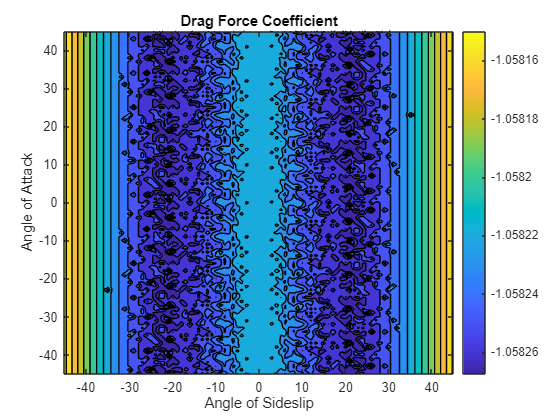

% Plot surface distribution
figure
load(pathOut,'aedb')
contourf((aedb.aos).*(180/pi), aedb.aoa.*(180/pi), aedb.aero.Cf_wX)
colorbar
xlabel('Angle of Sideslip')
ylabel('Angle of Attack')
title('Drag Force Coefficient')


%------------ END CODE -----------%